dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
network_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Project\Data-analytics\net.mat');
net = load(network_path);
% images = imageSet(dataset_path);
% perm = randperm(49676,20);
% for i = 1:20
%     subplot(4,5,i);
%     imshow(imds.Files{perm(i)});
% end
% labelCount = countEachLabel(imds)
% img = readimage(imds,1);
% size(img)
% numTrainFiles = 274;
layer = 2;
name = net.net.Layers(layer).Name;
channels = 1:8;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |       960.14 |               1 |
|           2 |       953.84 |               1 |
|           3 |       947.55 |               1 |
|           4 |       941.26 |               1 |
|           5 |       934.96 |               1 |
|           6 |       928.67 |               1 |
|           7 |       922.38 |               1 |
|           8 |       916.08 |               1 |
|           9 |       909.79 |               1 |
|          10 |       903.50 |               1 |
|==============================================|


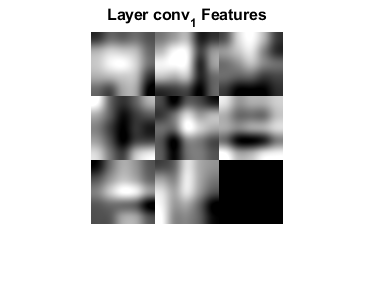

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 7;
name = net.net.Layers(layer).Name;
channels = 1:16;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         1.55 |               1 |
|           2 |         1.53 |               1 |
|           3 |         1.51 |               1 |
|           4 |         1.49 |               1 |
|           5 |         1.47 |               1 |
|           6 |         1.45 |               1 |
|           7 |         1.43 |               1 |
|           8 |         1.41 |               1 |
|           9 |         1.38 |               1 |
|          10 |         1.36 |               1 |
|==============================================|


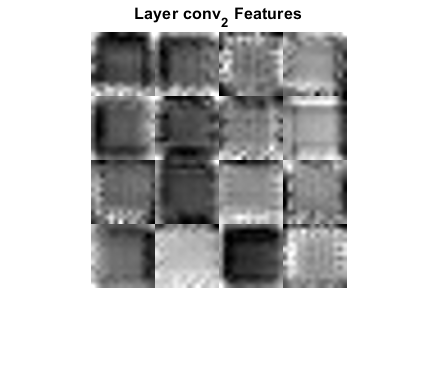

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 12;
name = net.net.Layers(layer).Name;
channels = 1:32;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.77 |               1 |
|           2 |         0.69 |               1 |
|           3 |         0.61 |               1 |
|           4 |         0.53 |               1 |
|           5 |         0.46 |               1 |
|           6 |         0.38 |               1 |
|           7 |         0.30 |               1 |
|           8 |         0.22 |               1 |
|           9 |         0.15 |               1 |
|          10 |         0.07 |               1 |
|==============================================|


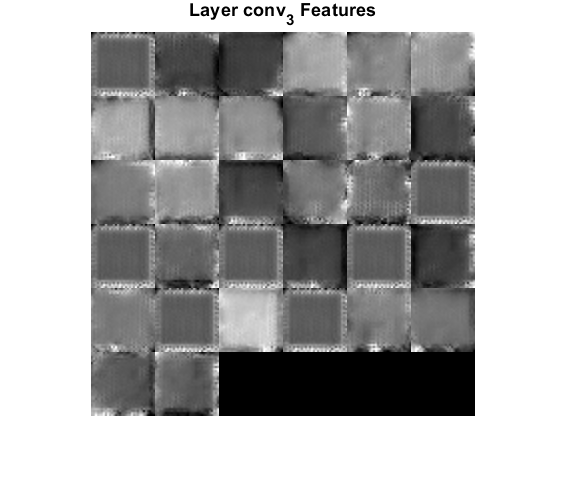

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 17;
name = net.net.Layers(layer).Name;
channels = 1:64;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.35 |               1 |
|           2 |         0.23 |               1 |
|           3 |         0.12 |               1 |
|           4 |         0.02 |               1 |
|           5 |         0.08 |               1 |
|           6 |         0.18 |               1 |
|           7 |         0.27 |               1 |
|           8 |         0.37 |               1 |
|           9 |         0.45 |               1 |
|          10 |         0.54 |               1 |
|==============================================|


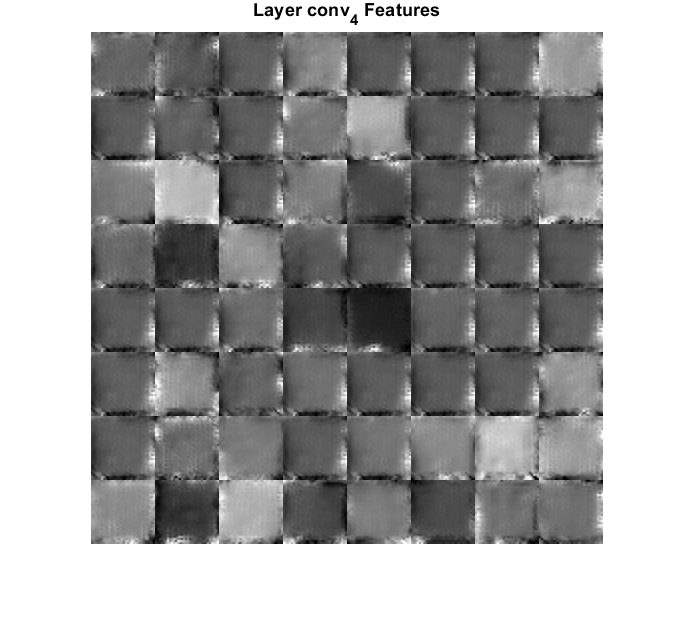

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 22;
name = net.net.Layers(layer).Name;
channels = 1:128;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.01 |               1 |
|           2 |         0.81 |               1 |
|           3 |         1.60 |               1 |
|           4 |         1.72 |               1 |
|           5 |         2.11 |               1 |
|           6 |         2.17 |               1 |
|           7 |         2.41 |               1 |
|           8 |         2.43 |               1 |
|           9 |         2.57 |               1 |
|          10 |         2.61 |               1 |
|==============================================|


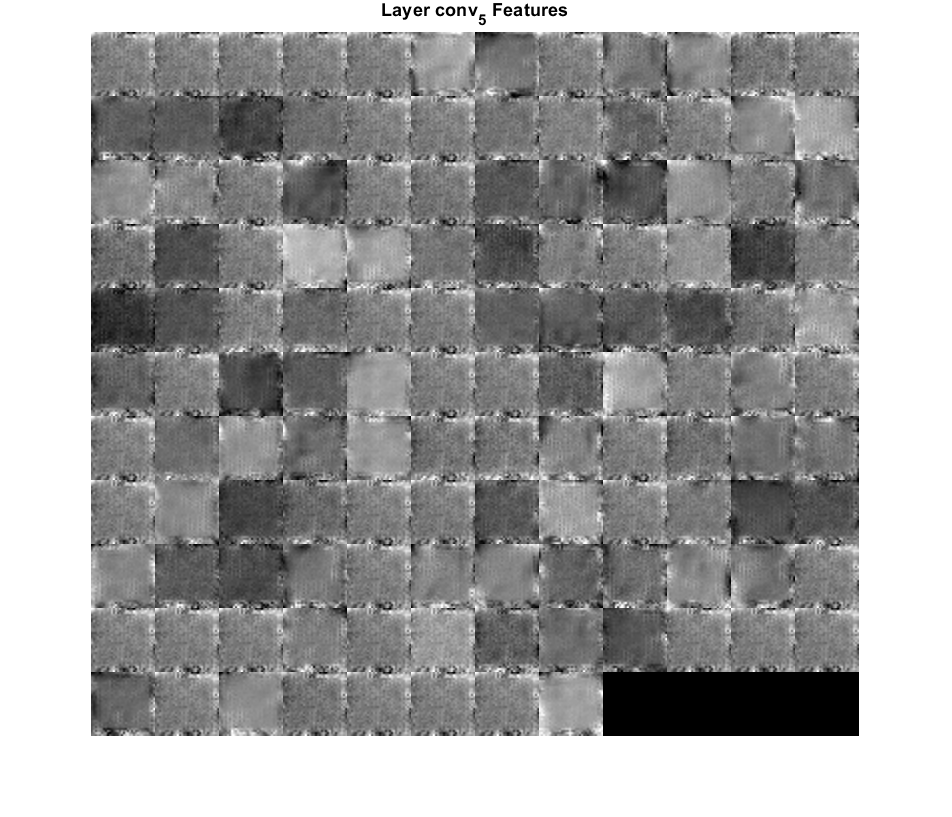

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

[imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.7, 0.15, 0.15,'randomized');
test_results = char(classify(net.net,imdsTest));
count = 0;
TestLabels = char(imdsTest.Labels);
for i = 1:length(test_results)
    comp = strcmp(TestLabels(i,:), test_results(i,:));
    if (comp == 1)
        count = count + 1;
    end
end
test_accuracy = count/length(test_results)

test_accuracy = 0.6661